lab10

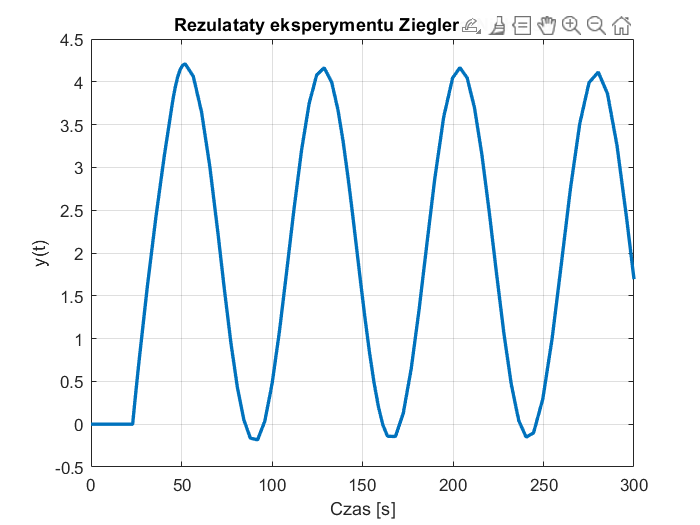

time =    52.2099
  127.9006


y =     4.1787
    4.1437


k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.3;
ki = 0;
kd = 0;

out = sim("model.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Rezulataty eksperymentu Zieglera-Nicholsa")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

[time, y] = ginput(2)


Tosc = time(2) - time(1)

Tosc = 75.6906

Regulator P

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.3;
kp = 0.5 * kr

kp = 1.6500

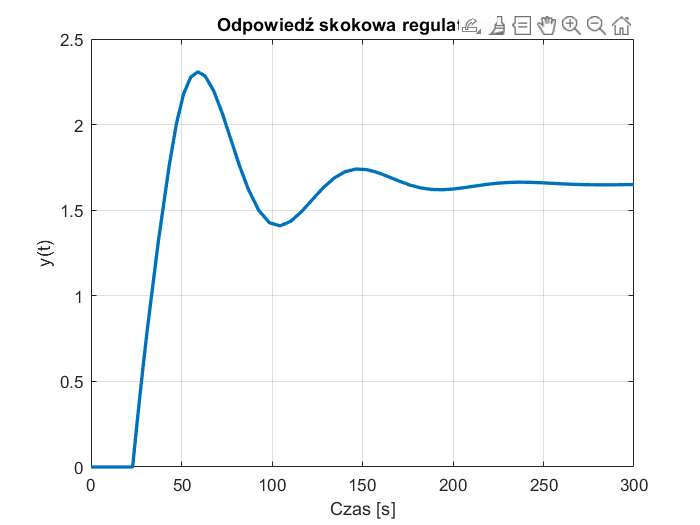

Ti = 0;
Td = 0;
ki = 0;
kd = 0;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa regulatora P")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

Regulator PI

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.3;
kp = 0.45 * kr

kp = 1.4850

Ti = 0.85 * Tosc

Ti = 64.3370

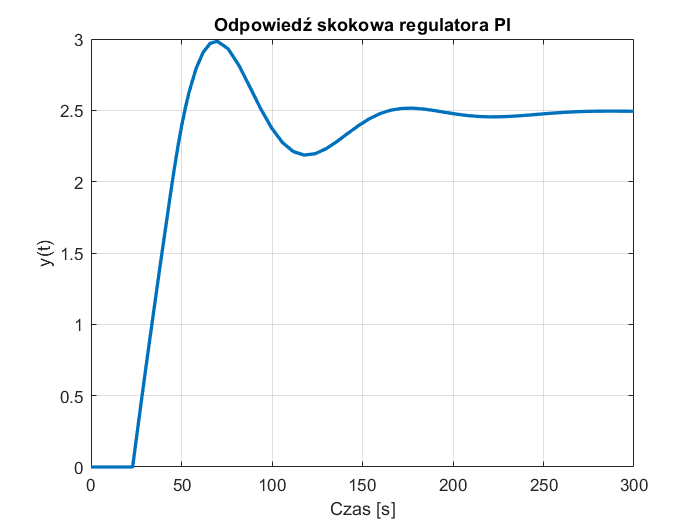

Td = 0;
ki = kp/Ti;
kd = 0;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa regulatora PI")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

Regulator PID

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.3;
kp = 0.6 * kr

kp = 1.9800

Ti = 0.5 * Tosc

Ti = 37.8453

Td = 0.12 * Tosc

Td = 9.0829

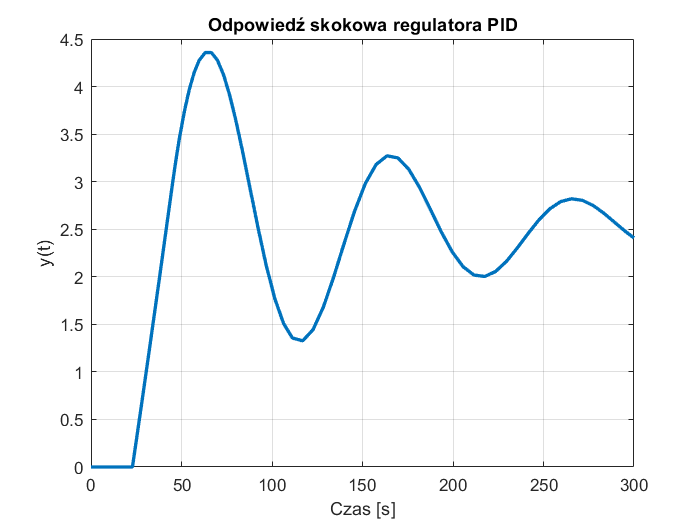

ki = kp/Ti;
kd = kp/Td;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa regulatora PID")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

Metoda Astroma-Hagglunda

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.359;
kp = 0.6 * kr

kp = 2.0154

Ti = 0.5 * Tosc

Ti = 38.6740

Td = 0.12 * Tosc

Td = 9.2818

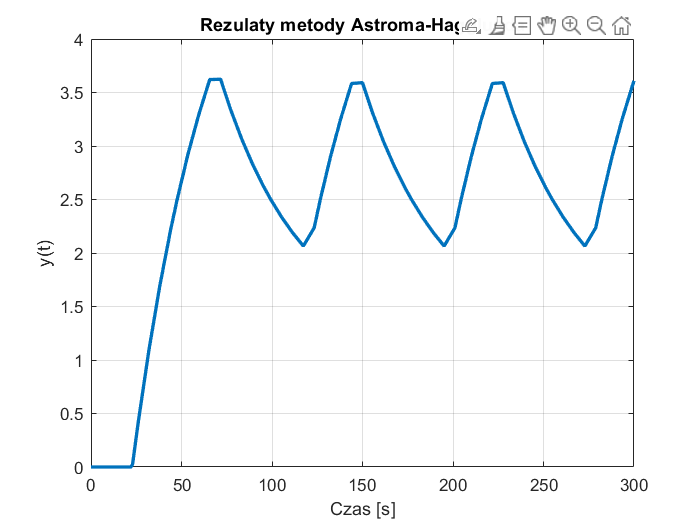

time =    69.3370
  147.2376


y =     3.6121
    3.5841


ki = kp/Ti;
kd = kp/Td;

out = sim("model2.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Rezulaty metody Astroma-Hagglunda")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

[time, y] = ginput(2)


Tosc = time(2) - time(1)

Tosc = 77.9006

Regulator P

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.359;
kp = 0.5 * kr

kp = 1.6795

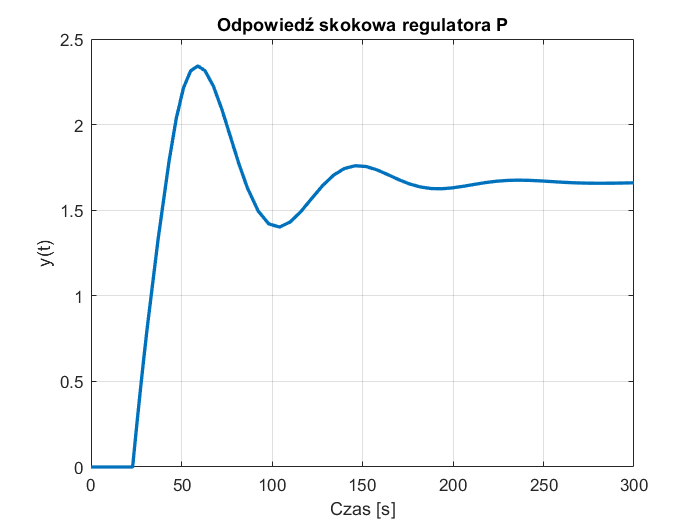

Ti = 0;
Td = 0;
ki = 0;
kd = 0;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa regulatora P")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

Regulator PI

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.359;
kp = 0.45 * kr

kp = 1.4850

Ti = 0.85 * Tosc

Ti = 65.7459

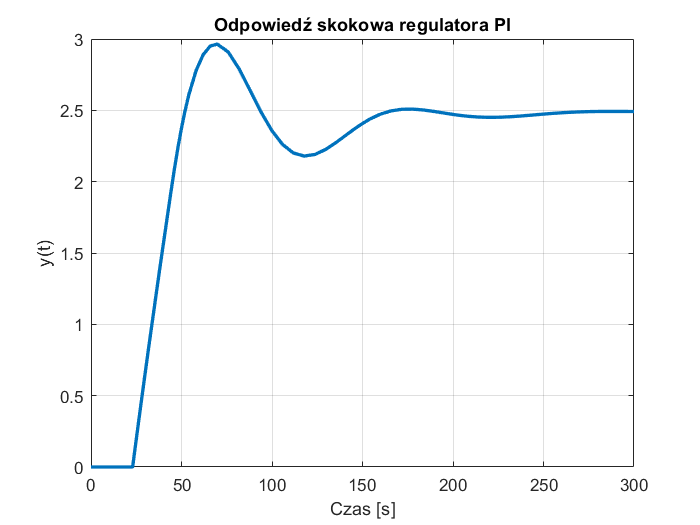

Td = 0;
ki = kp/Ti;
kd = 0;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa regulatora PI")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

Regulator PID

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.359;
kp = 0.6 * kr

kp = 2.0154

Ti = 0.5 * Tosc

Ti = 38.9503

Td = 0.12 * Tosc

Td = 9.3481

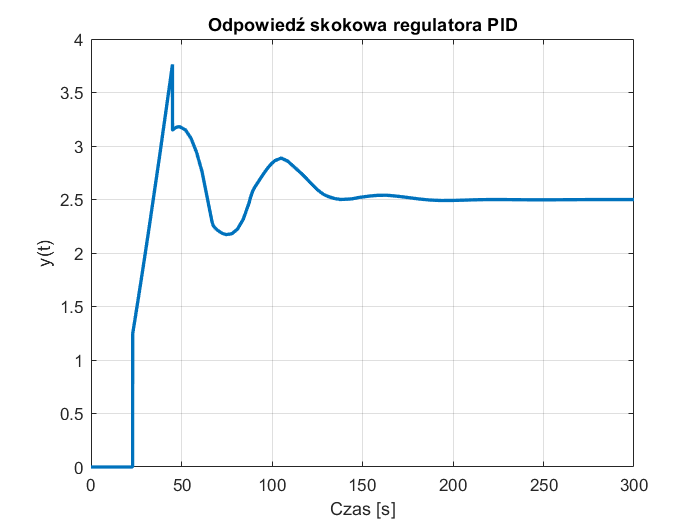

ki = kp/Ti;
kd = kp*Td;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa regulatora PID")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

Dostrajanie regulatora PID na podstawie parametrów transmitancji zastępczej

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.359;
kp = (0.95*T) / (tau*k);
Ti = 0.5 * Tosc

Ti = 38.9503

Td = 0.12 * Tosc

Td = 9.3481

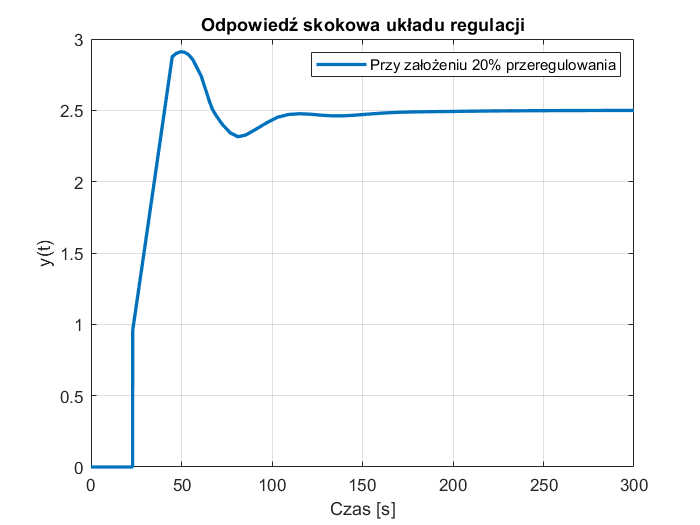

ki = kp/(2.4 * tau);
kd = kp*0.4*tau;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa układu regulacji")
legend("Przy założeniu 20% przeregulowania")
ylabel("y(t)")
xlabel("Czas [s]")
grid on

k = 1.18;
tau = 22;
T = 45;
r = 2.5;
kr = 3.359;
kp = (1.4*T) / (tau*k);
Ti = 0.5 * Tosc

Ti = 38.9503

Td = 0.12 * Tosc

Td = 9.3481

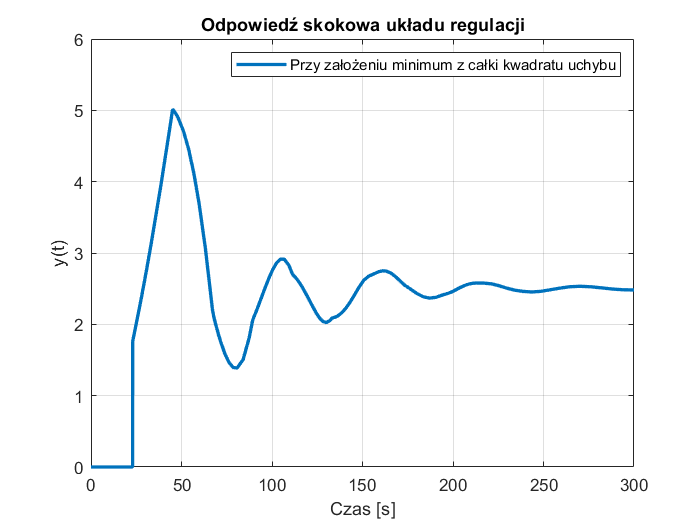

ki = kp/(1.3 * tau);
kd = kp*0.5*tau;

out = sim("model1.slx");
plot(out.y.time, out.y.signals.values, "LineWidth", 2)
title("Odpowiedź skokowa układu regulacji")
legend("Przy założeniu minimum z całki kwadratu uchybu")
ylabel("y(t)")
xlabel("Czas [s]")
grid on